clc;
clear all;
close all;

## objective function, first decide which function we want to optimize

ObjFun = @(x)Sphere(x); % define and specify any function we want to
D = 2; % dimensions of search space or no of features
Xmin = -50; % min value of search variable, lower bound
Xmax = 50; % max value of search variable, upper bound
Maxiter=20; % max number of iterations

## initialization of PSO parameters,


N = 2; % neighbourhood size
P=8; % No of particles in swarm
c = [2,2]; % acceleration coeffeicients, personal and social
iwt = 1;  % intertia weight
%iwt=0.9-(1:Maxiter).*(0.5./Maxiter)
% iwt=0.5.*ones(1,Maxiter);
neighbor= topology('ring', P, N)

neighbor =      0     1     1     0     0     0     1     1
     1     0     1     1     0     0     0     1
     1     1     0     1     1     0     0     0
     0     1     1     0     1     1     0     0
     0     0     1     1     0     1     1     0
     0     0     0     1     1     0     1     1
     1     0     0     0     1     1     0     1
     1     1     0     0     0     1     1     0



if length(Xmin)==1
    Xmin=repmat(Xmin,1,D);
    Xmax=repmat(Xmax,1,D);
end
mv=0.5*(Xmax-Xmin);
Xmin=repmat(Xmin,P,1);
Xmax=repmat(Xmax,P,1);
Vmin=repmat(-mv,P,1); % clamping the velocity of particles else it can fly over good solutions
Vmax=-Vmin;


topology

topology('scalefree', P, N) %'random', 'star', 'ring', 'fully connected'

ans =      0     1     1     1     0     0     1     0
     1     0     1     1     1     0     0     0
     1     1     0     0     0     1     1     1
     1     1     0     0     1     0     0     0
     0     1     0     1     0     1     0     1
     0     0     1     0     1     0     0     0
     1     0     1     0     0     0     0     0
     0     0     1     0     1     0     0     0


## every particle has a position, velocity , cost function value or cost, personal best nassociated with it

global best

pos=Xmin+(Xmax-Xmin).*rand(P,D);

for i=1:P
    e(i,1)=ObjFun (pos(i,:));
end


vel=Vmin+2.*Vmax.*rand(P,D);%initialize the velocity of the particles
pbest=pos;
pbestval=e; %initialize the pbest and the pbest's fitness value
[gbestval,gbestid]=min(pbestval);
gbest=pbest(gbestid,:);%initialize the gbest and the gbest's fitness value
gbestrep=repmat(gbest,P,1);


**Iterations**

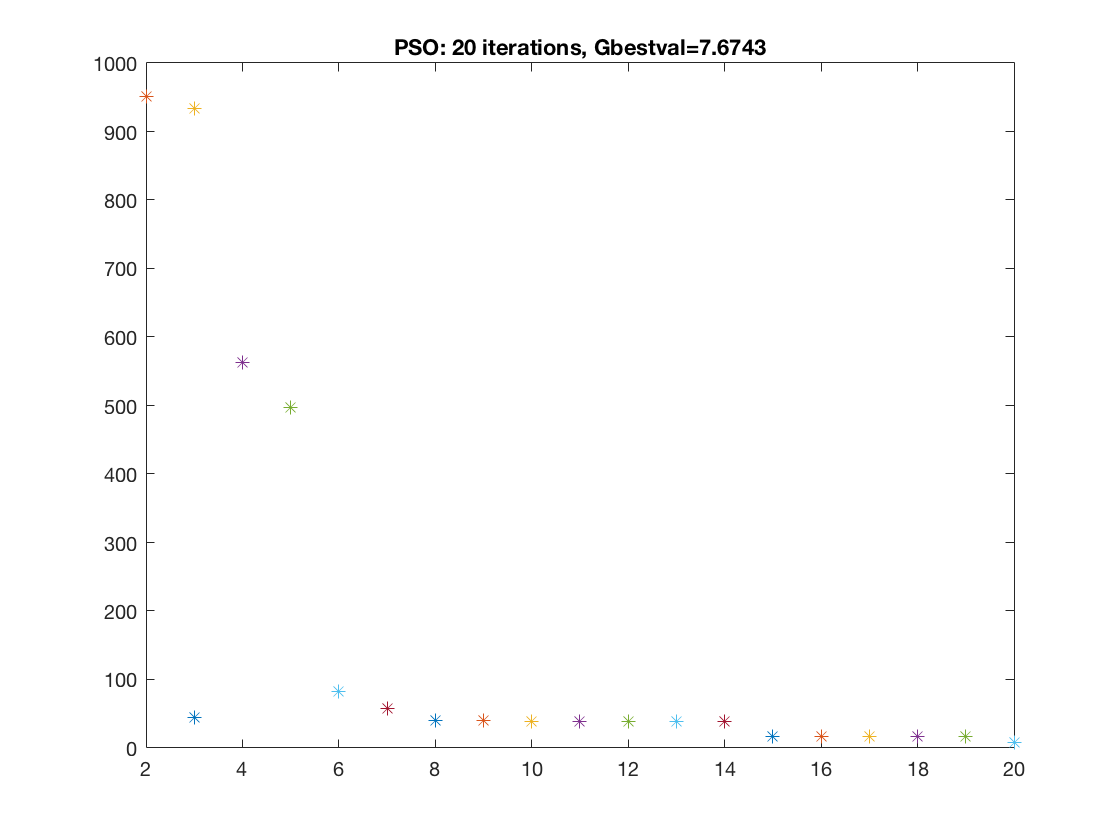


for i=2:Maxiter
    
    for k=1:P
        
        
        [tmp,~]=min(pbestval(logical(neighbor(k,:)))); % look at the neighbors for best 
        tmpid= find(pbestval==tmp); % find index with minimum value 
        aa(k,:)=c(1).*rand(1,D).*(pbest(k,:)-pos(k,:))+ c(2).*rand(1,D).*(pbest(neighbor(k,tmpid),:)-pos(k,:));
        %vel(k,:)=iwt(i).*vel(k,:)+aa(k,:);
        vel(k,:)=iwt.*vel(k,:)+aa(k,:); % velocity update
        
        vel(k,:)=(vel(k,:)>mv).*mv+(vel(k,:)<=mv).*vel(k,:); % velocity clamping
        vel(k,:)=(vel(k,:)<(-mv)).*(-mv)+(vel(k,:)>=(-mv)).*vel(k,:);
        pos(k,:)=pos(k,:)+vel(k,:); % position update
        
        pos(k,:)=((pos(k,:)>=Xmin(1,:))&(pos(k,:)<=Xmax(1,:))).*pos(k,:)...
            +(pos(k,:)<Xmin(1,:)).*(Xmin(1,:)+0.25.*(Xmax(1,:)-Xmin(1,:)).*rand(1,D))+(pos(k,:)>Xmax(1,:)).*(Xmax(1,:)-0.25.*(Xmax(1,:)-Xmin(1,:)).*rand(1,D));
        
        e(k,1) = ObjFun(pos(k,:)); % calculate cost
       
        tmp=(pbestval(k)<e(k));
        temp=repmat(tmp,1,D);
        pbest(k,:)=temp.*pbest(k,:)+(1-temp).*pos(k,:);
        pbestval(k)=tmp.*pbestval(k)+(1-tmp).*e(k);%update the pbest
        if pbestval(k)<gbestval
            gbest=pbest(k,:);
            gbestval=pbestval(k);
            gbestrep=repmat(gbest,P,1);%update the gbest
        end
    end
    
    figure(4), plot(i,gbestval,'*'), hold on
    title(['PSO: ',num2str(i),' iterations, Gbestval=',num2str(gbestval)]);
end


gbestval, gbest

gbestval = 7.6743

gbest =     2.6481   -0.8137


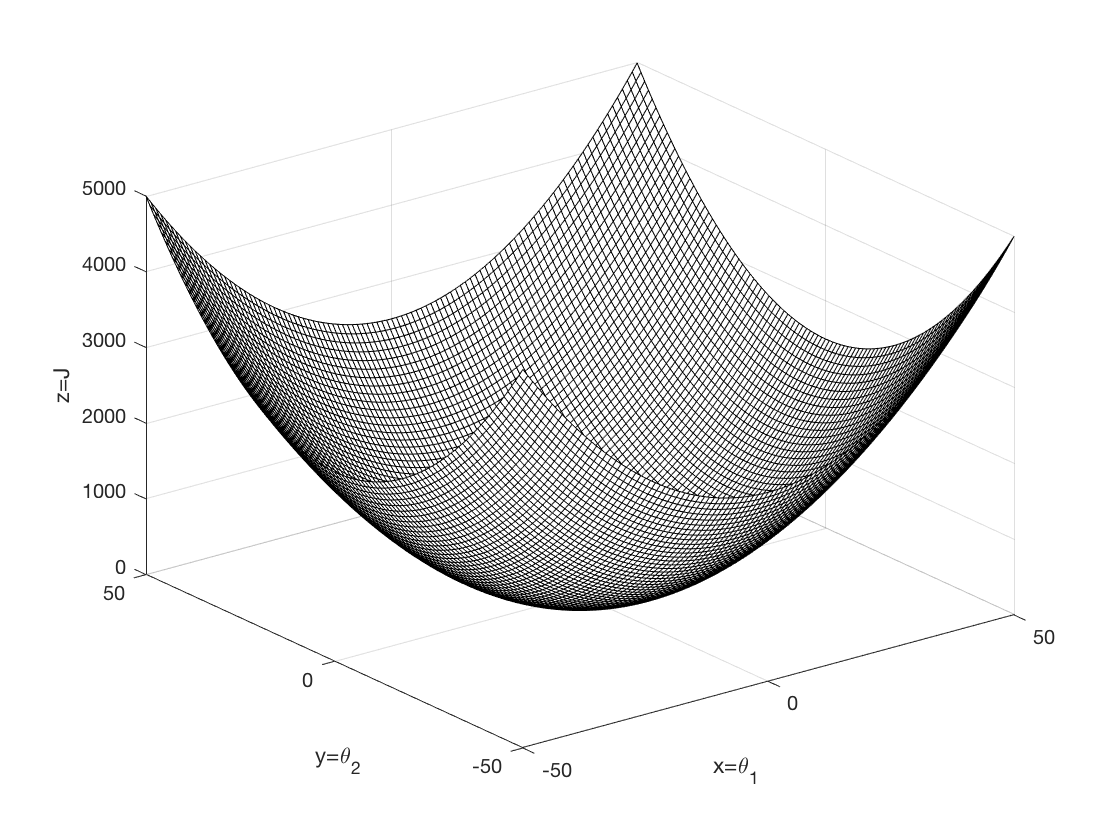

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Plot the function we are seeking the minimum of:
% 
x=Xmin:1:Xmax;   % For our function the range of values we are considering
y=x;

% Compute the function that we are trying to find the minimum of.

for jj=1:length(x)
    for ii=1:length(y)
        z(ii,jj)=ObjFun([x(jj);y(ii)]);
        %		z(ii,jj)=nutrientsfunc1([x(jj);y(ii)],flag);
    end
end

% % First, show the actual function to be maximized
% 
figure(1)
clf
surf(x,y,z);
colormap(jet)
% Use next line for generating plots to put in black and white documents.
colormap(white);
xlabel('x=\theta_1');
ylabel('y=\theta_2');
zlabel('z=J');

%title('Nutrient concentration (valleys=food, peaks=noxious)');